clear all
close all
%script para resolver los ejercicios uno y dos
mu = 1 %coeficiente de rozamiento

mu = 1

k=3 %constante de los resortes

k = 3


%x1 desplazazamiento bloque 1 bloque 1
%x2 desplazamiento  bloque 2
%x3 velocidad bloque 1
%x4 velocidad bloque 2

A=[0 0 1 0
    0 0 0 1
    -2*k k -mu 0
    k -2*k 0 -mu]

A =      0     0     1     0
     0     0     0     1
    -6     3    -1     0
     3    -6     0    -1


B=[0 0 1 0]'

B =      0
     0
     1
     0


C = [0 1 0 0]

C =      0     1     0     0


%Controlabilidad
co =ctrb(A,B)

co =      0     1    -1    -5
     0     0     0     3
     1    -1    -5    11
     0     0     3    -6


rco=rank(co)

rco = 4

%observabilidad
ob = obsv(A,C)

ob =      0     1     0     0
     0     0     0     1
     3    -6     0    -1
    -3     6     3    -5


rob=rank(ob)

rob = 4



%polos en lazo abierto
[avec,lambda]=eig(A)

avec =   -0.0373 - 0.2205i  -0.0373 + 0.2205i  -0.1021 - 0.3385i  -0.1021 + 0.3385i
   0.0373 + 0.2205i   0.0373 - 0.2205i  -0.1021 - 0.3385i  -0.1021 + 0.3385i
   0.6708 + 0.0000i   0.6708 + 0.0000i   0.6124 + 0.0000i   0.6124 + 0.0000i
  -0.6708 - 0.0000i  -0.6708 + 0.0000i   0.6124 + 0.0000i   0.6124 - 0.0000i


lambda =   -0.5000 + 2.9580i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5000 - 2.9580i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 1.6583i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 1.6583i


%Consideramos unas condiciones iniciales arbitrarias pero compatibles con
%el sistema,
x0 = [-0.5,0.7,0.2,0.3]

x0 =    -0.5000    0.7000    0.2000    0.3000


u = 0

u = 0

tf = 15

tf = 15

sys = @(t,x)bloques(t,x,A,B,u,x0)

sys = function_handle with value:
    @(t,x)bloques(t,x,A,B,u,x0)


[t,x] = ode45(sys,[0,tf],x0);
plot(t,x+kron(ones(size(x,1),1),[1 2 0 0]))

%Los polos del sistema original son complejos conjugados
k = acker(A,B,[-2 -2 -5 -5])

k =    44.0000  -63.6667   12.0000    4.0000


%construimos el sistema realimentado
Ac = A-B*k

Ac =          0         0    1.0000         0
         0         0         0    1.0000
  -50.0000   66.6667  -13.0000   -4.0000
    3.0000   -6.0000         0   -1.0000


x0 = [-0.5,0.7,0.2,0.3]

x0 =    -0.5000    0.7000    0.2000    0.3000


u = 0

u = 0

tf = 15

tf = 15

sys = @(t,x)bloques(t,x,Ac,B,u,x0)

sys = function_handle with value:
    @(t,x)bloques(t,x,Ac,B,u,x0)


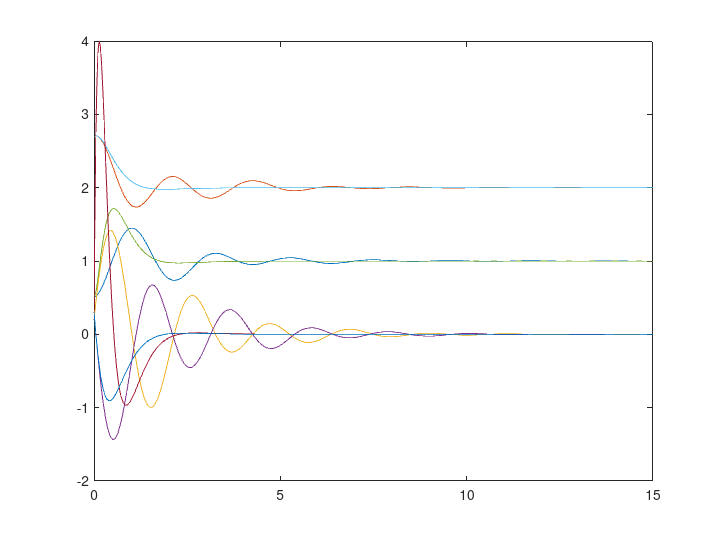

[t,x] = ode45(sys,[0,tf],x0);
hold on
plot(t,x+kron(ones(size(x,1),1),[1 2 0 0]))


%vamos a añadir control integral
%en primer intentamos ver si es posible controlar los dos bloques
C2 = [1 0 0 0; 0 1 0 0]

C2 =      1     0     0     0
     0     1     0     0



Aamp = [A zeros(4,2)
    C2 zeros(2)]

Aamp =      0     0     1     0     0     0
     0     0     0     1     0     0
    -6     3    -1     0     0     0
     3    -6     0    -1     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0


Bamp = [B; 0; 0]

Bamp =      0
     0
     1
     0
     0
     0


Cint = [C2; zeros(2,4)]

Cint =      1     0     0     0
     0     1     0     0
     0     0     0     0
     0     0     0     0


%analizamos controlabilidad del ampliado
rcoI = rank(ctrb(Aamp,Bamp))

rcoI = 5

Tenemos rango cinco, por lo que no podemos controlar los dos bloques a la vez. Probamos ahora ver si al menos es posible controlar el observado.


Aamp = [A zeros(4,1)
        C  0]

Aamp =      0     0     1     0     0
     0     0     0     1     0
    -6     3    -1     0     0
     3    -6     0    -1     0
     0     1     0     0     0


Bamp = [B; 0]

Bamp =      0
     0
     1
     0
     0


Camp = [C 0]

Camp =      0     1     0     0     0


%analizamos controlabilidad del ampliado
rcoI = rank(ctrb(Aamp,Bamp))

rcoI = 5

% recalculamos ahora la posición de los polos añadiendo 1 a la izquierda de
% los anteriores pero conservando la posición de los que ya tenemos
kamp = acker(Aamp,Bamp,[-2 -2 -5 -5 -5])

kamp =   109.0000   39.6667   17.0000   87.3333  166.6667


%reconstruimos el sistema con el integrador
A_int = [A-B*kamp(1:4)  -B*kamp(5)
    C                0]

A_int =          0         0    1.0000         0         0
         0         0         0    1.0000         0
 -115.0000  -36.6667  -18.0000  -87.3333 -166.6667
    3.0000   -6.0000         0   -1.0000         0
         0    1.0000         0         0         0


Bf = [0;0;0;0;-1]

Bf =      0
     0
     0
     0
    -1


Atencion: El Bf que acabo e definir es ficticio, en realidad estoy aprovechando B para introducir la consigna yd, y así emplear la misma función de antes

x0 = [-0.5,0.7,0.2,0.3,0] %añado un 0 al integral

x0 =    -0.5000    0.7000    0.2000    0.3000         0


Añadimos condición inicial como desplazamiento respecto al equilibrio del segundo bloque

yd = 0.35

yd = 0.3500

tf = 15

tf = 15

sys = @(t,x)bloques(t,x,A_int,Bf,yd,x0)

sys = function_handle with value:
    @(t,x)bloques(t,x,A_int,Bf,yd,x0)


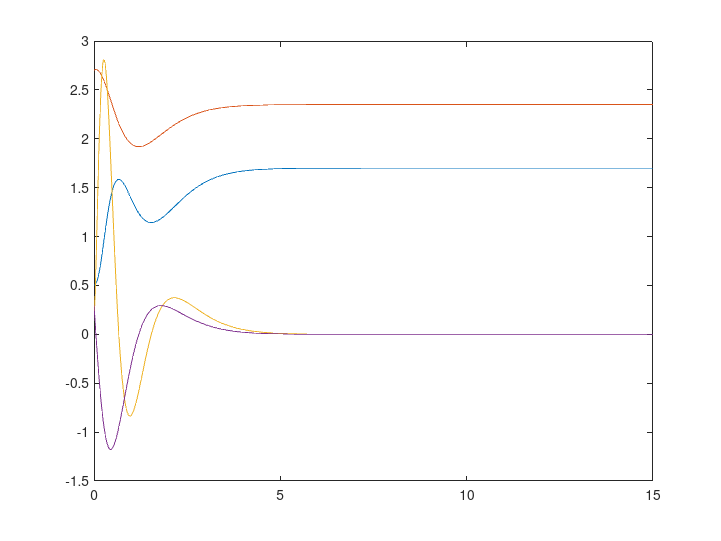

[t,x] = ode45(sys,[0,tf],x0);
figure()
plot(t,x(:,1:4)+kron(ones(size(x,1),1),[1 2 0 0]))




%figure()

%estimador de estados
%debemos calcular ahora unos polos para el observador
L = acker(A',C',[-5 -5 -6 -6])'

L =   126.6667
   20.0000
 -131.6667
  128.0000


%reconstruimos el sistema incluyendo el observador. Incluimos ya todos los
%valores calculado en las secciones anteriores. El principio de separación
%hace que no tengamos que recalcular nada más
A_obs = [A, -B*kamp(1:4), -B*kamp(5)
    L*C, A-B*kamp(1:4)-L*C,-B*kamp(5)
    C, zeros(1,5)]

A_obs =          0         0    1.0000         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
   -6.0000    3.0000   -1.0000         0 -109.0000  -39.6667  -17.0000  -87.3333 -166.6667
    3.0000   -6.0000         0   -1.0000         0         0         0         0         0
         0  126.6667         0         0         0 -126.6667    1.0000         0         0
         0   20.0000         0         0         0  -20.0000         0    1.0000         0
         0 -131.6667         0         0 -115.0000   95.0000  -18.0000  -87.3333 -166.6667
         0  128.0000         0         0    3.0000 -134.0000         0   -1.0000         0
         0    1.0000         0         0         0         0         0         0         0



Bf2 = [0;0;0;0;0;0;0;0;-1] %ficticio

Bf2 =      0
     0
     0
     0
     0
     0
     0
     0
    -1


x0 = [-0.5,0.7,0.2,0.3,0,0,0,0,0]

x0 =    -0.5000    0.7000    0.2000    0.3000         0         0         0         0         0


yd = 0.35

yd = 0.3500

tf = 15

tf = 15

sys = @(t,x)bloques(t,x,A_obs,Bf2,yd,x0)

sys = function_handle with value:
    @(t,x)bloques(t,x,A_obs,Bf2,yd,x0)


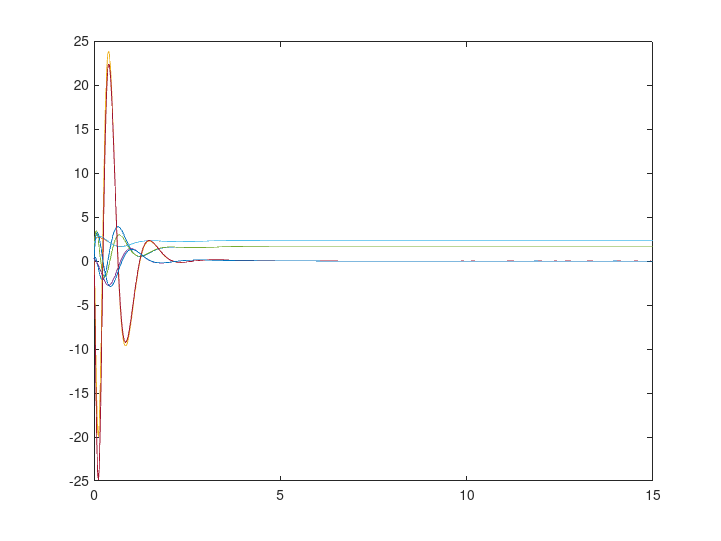

[t,x] = ode45(sys,[0,tf],x0);
figure()
plot(t,x(:,1:8)+kron(ones(size(x,1),1),[1 2 0 0 1 2 0 0]))

function dotx = bloques(t,x,A,B,u,x0)
dotx = A*x+ B*u;
end
%Para dibujar los bloques, no es parte del examen
%pongo arbitrariamente la posición de reposo de los bloques en 2 y 5
% x1 = x(:,1)+3
% x2 = x(:,2)+6
% figure()
% for i = 1:length(x1)kron(ones(1,size(x,2)),[1,2,0,0])
%     plot(linspace(0,x1(i),30),0.025*ones(1,30),'.k')
%     hold on
%     plot(linspace(x1(i),x2(i),30),0.025*ones(1,30),'.k')
%     plot(linspace(x2(i),9,30),0.025*ones(1,30),'.k')
%     rectangle('position',[x1(i)-0.3 0 0.6 0.05],'FaceColor','b')
%     rectangle('position',[x2(i)-0.3 0 0.6 0.05],'FaceColor','r')
%     axis([0 9 0 0.5])
%     drawnow
%     hold off
% end